## Cvičení 6: - Polynomy (mnohočleny)


$$f\left(x\right)=-\frac{x^3 }{3}\;+x^2 +2\cdot x+6$$


*háček: neuronové sítě (skoro)*

Super pomocník: https://www.desmos.com/calculator

% p = [-1/3, 1, 2, 6];


$$f_2 \left(x\right)=x^4 +x^3$$


% p2 = [1 1 0 0 0];

Vyčíslení hodnoty v bodě:

% polyval(p,1:10);

Vykreslení:

% x = -2:0.1:5
% plot(x,polyval(p,x));
% grid on;
% hold on;

Řád polynomu:

% M = length(p)-1

Hledání maxima:

% [max_val,max_ind] = max(polyval(p,x));
% plot(x(max_ind),max_val,"ok");
% hold off;

Konvoluce: (součet pronásobení vektorů)

*Např. mám systém, jež jsem schopný popsat určitým vektorem. Pokud vemu další vektor, představující signál vstupující do systému. Konvoluce je potom výstup daného systému.  *

% x = [1 0 0 0 0 0];
% x2 = [0 0 0 1 1 1];
% y = [0 0 1 1 0 0];
% 
% conv(x,y)
% conv(x2,y)
% 
% % deconv(x,y); % Dekonvoluce (dělení)

Kořeny polynomu:

*Hodnoty, pro které je funkční hodnota polynomu je nula. (Nemusí být jen reálné!)*

% roots(p)
% 
% polyval(p,roots(p))

Kvadratická rovnice:


$$f\left(x\right)=x^2 +2x-3$$



$$a=1,b=2,c=-3$$



$$D=b^2 -4\mathrm{ac}=2^2 -4\cdot 1\cdot \left(-3\right)=16$$



$$x_{1,2} =\frac{\pm b+\sqrt{D}}{2a}=1,-3$$


% p = [1 2 -3];
% p2 = [2 4 -6];
% r = roots(p)

Získání polynomu z kořenů:

% poly(r)
% poly(roots(p2))

Polynomiální regrese:

(zkusíme zjistit závislost výšky a věku)

% vek = [15 18 23 28 30 37 45];
% vyska = [182 175 169 185 191 181 175];
% figure
% plot(vek,vyska,"o");
% hold on;
% 
% M = 5
% 
% p = polyfit(vek,vyska,M);
% vek = 15:45
% plot(vek,polyval(p,vek));
% 
% polyval(p,35)

*Jakákoliv data dokážu proložit. Pro více vstupů, pro více výstupů. Na takhle jednoduchém principu proložení dat pracují neuronové sítě. Narvu jim hodně hodnot a řeknu jim, jaké hodnoty očekávám na výstupu. Ony potom jen tupě vrací hodnotu mého modelu.*

### *Úkoly:*

#### *1. Zjistit řád, kořeny, a násldně zkusit zpět převést na polynom. Nakonec vykreslit od 1 do 5 s krokem 0,1: *


$$f\left(x\right)=x^5 -15x^4 +{85x}^3 {-225x}^2 +274x-120$$


p = [1 -15 85 -225 274 -120];
M = length(p)-1

M = 5

r = roots(p)

r =     5.0000
    4.0000
    3.0000
    2.0000
    1.0000


poly(r)

ans =     1.0000  -15.0000   85.0000 -225.0000  274.0000 -120.0000


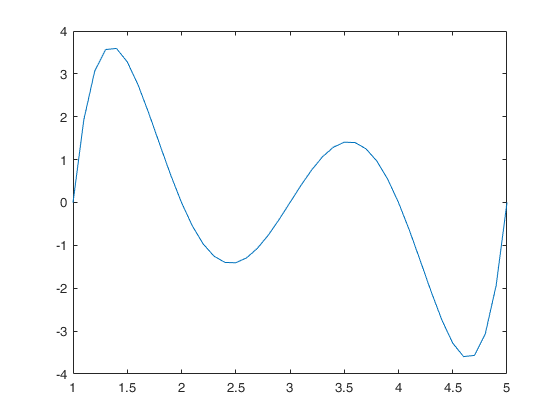


x = 1:0.1:5;
plot(x,polyval(p,x));

#### *2. Najděte polynom s kořeny: [158 150 156 112] a zětným vyšetřením polynomu výpočet zkontrolujte:*

r = [158 150 155 156 112];
p = poly(r)'

p = 	1.0e+10 *

    0.0000
   -0.0000
    0.0000
   -0.0031
    0.2233
   -6.4183


roots(p)

ans =   158.0000
  156.0000
  155.0000
  150.0000
  112.0000


#### *3. Proložte neměřené hodnoty polynomy řádu 1 až 15. Vykreslete je s krokem 0,01:*

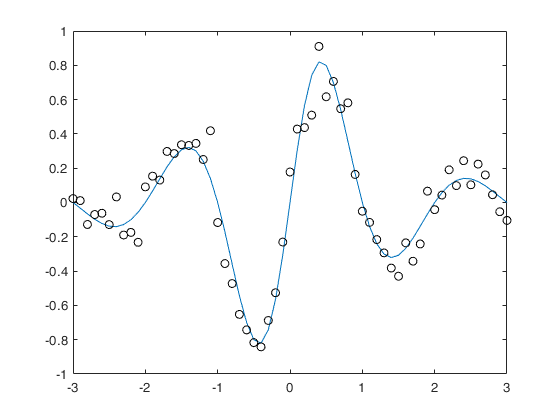

x = -3:0.1:3;
y = sin(pi*x)./(x.^2 + 1);

plot(x,y);
hold on;

t = awgn(y,20); % zašuměnní dat
plot(x,t,"ok");

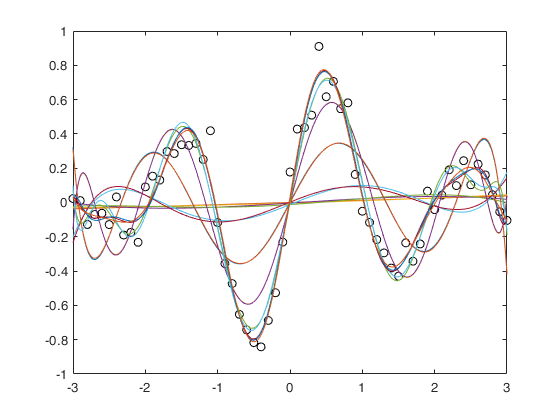


figure
plot(x,t,"ok");
hold on;


for M = 1:15
    p = polyfit(x,t,M);
    x2 = -3:0.01:3;
    plot(x2,polyval(p,x2));
end